# Examples 3.3 and 3.9: Flow Cytometer Data (Discrete)

Note: this script reproduces Examples 3.3 (Section 3.2) and 3.9 (Section 3.4) of **Statistics for Chemical Engineers**: forward (FSC) and side (SSC) scatter of droplets, each grouped in low, medium, and high values. Victor Z UW-Madison, 2020 flow cytometer data

clc;  clear all; close all hidden; 

load('./Data/flow_cytometer.dat');
 data=flow_cytometer;
 n=length(data);

%load('./Data/flow_cytometer.mat')
%n=length(data);

FSC=data(:,1);
SSC=data(:,2);

minFSC=min(FSC)

minFSC = 4.2365

maxFSC=max(FSC)

maxFSC = 6.0834


minSSC=min(SSC)

minSSC = 3.6191

maxSSC=max(SSC)

maxSSC = 5.8543

## Joint pdf (Example 3.3)

get joint pdf

 figure(1)
 plot(FSC,SSC,'blacko','MarkerFaceColor','w','MarkerSize',1)
 xlabel('$\log \textrm{FSC}$','Interpreter','latex','FontSize',16)
 ylabel('$\log \textrm{SSC}$','Interpreter','latex','FontSize',16)
 set(gca,'FontSize',16)
 hold on

% bin data in mxm matrix
m=3;
[freq,SSCedges,FSCedges]=histcounts2(SSC,FSC,m)

freq =         2613           0           0
        5994        1114           0
          28         239          12


SSCedges =     3.5000    4.3000    5.1000    5.9000


FSCedges =     4.2000    4.9000    5.6000    6.3000


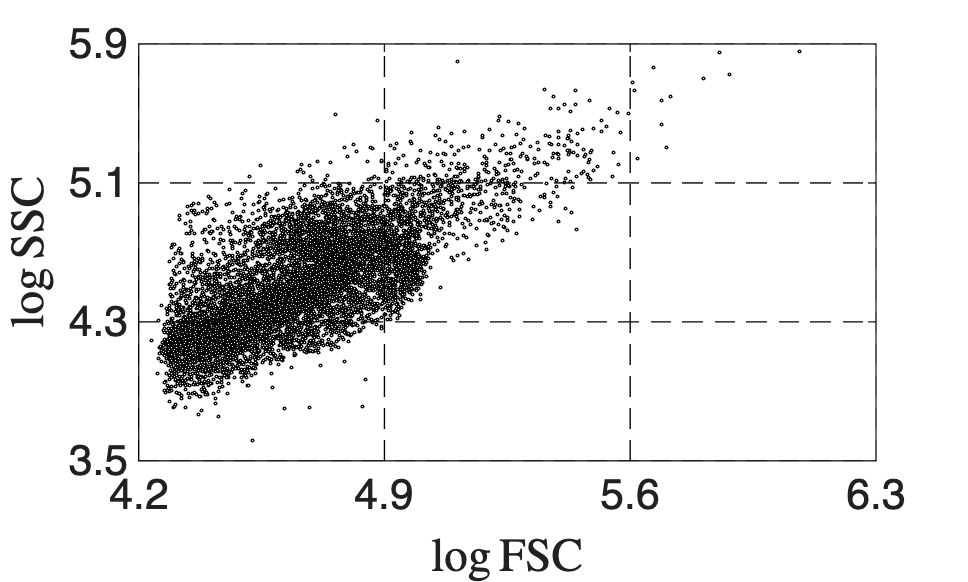


jointpdf=freq/n;

for i=1:m+1
    xx=linspace(min(FSCedges),max(FSCedges),100);
    plot(xx,SSCedges(i)*ones(100,1),'black--')
    hold on
end
for j=1:m+1
    yy=linspace(min(SSCedges),max(SSCedges),100);
    plot(FSCedges(j)*ones(100,1),yy,'black--')
end
 xticks(FSCedges)
 yticks(SSCedges)
 axis([min(FSCedges) max(FSCedges) min(SSCedges) max(SSCedges)])

print -depsc ch3_flow_cytometer_data.eps

## Marginal pdfs

get marginal pdfs

[freqmargFSC,FSCedgesmarg]=histcounts(FSC,m);

marFSC=freqmargFSC/n

marFSC =     0.8635    0.1353    0.0012



[freqmargSSC,SSCedgesmarg]=histcounts(SSC,m);

marSSC=freqmargSSC/n

marSSC =     0.2613    0.7108    0.0279


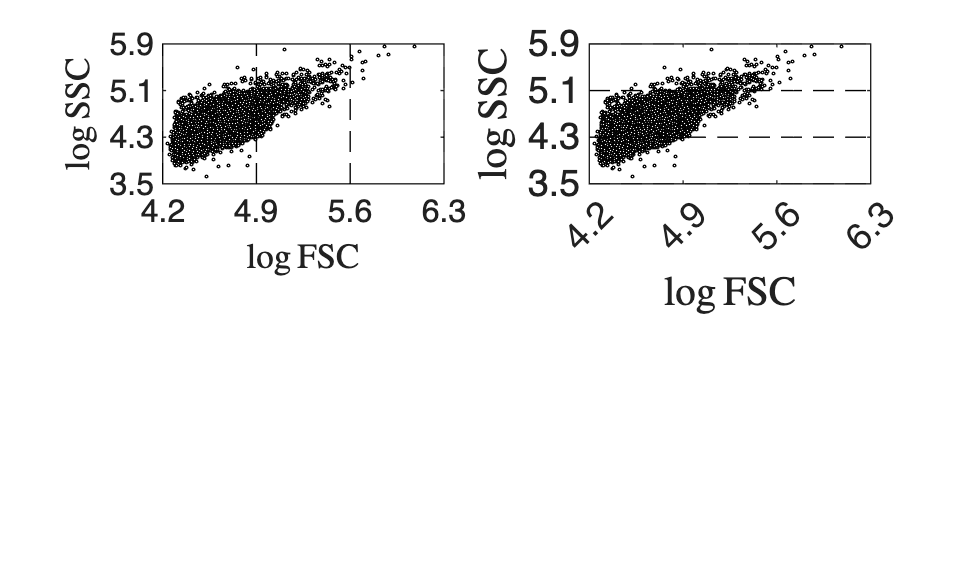


figure(2)
subplot(2,2,2)
plot(FSC,SSC,'blacko','MarkerFaceColor','w','MarkerSize',1)
xlabel('$\log \textrm{FSC}$','Interpreter','latex','FontSize',16)
ylabel('$\log \textrm{SSC}$','Interpreter','latex','FontSize',16)
set(gca,'FontSize',14)
hold on
for i=1:m+1
    xx=linspace(min(FSCedges),max(FSCedges),100);
    plot(xx,SSCedges(i)*ones(100,1),'black--')
    hold on
end
 xticks(FSCedges)
 yticks(SSCedges)
 axis([min(FSCedges) max(FSCedges) min(SSCedges) max(SSCedges)])

subplot(2,2,1)
plot(FSC,SSC,'blacko','MarkerFaceColor','w','MarkerSize',1)
xlabel('$\log \textrm{FSC}$','Interpreter','latex','FontSize',16)
ylabel('$\log \textrm{SSC}$','Interpreter','latex','FontSize',16)
set(gca,'FontSize',12)
hold on
for j=1:m+1
    yy=linspace(min(SSCedges),max(SSCedges),100);
    plot(FSCedges(j)*ones(100,1),yy,'black--')
end
 xticks(FSCedges)
 yticks(SSCedges)
 axis([min(FSCedges) max(FSCedges) min(SSCedges) max(SSCedges)])

print -depsc ch3_flow_cytometer_data_marg.eps

## Conditional pdfs (Example 3.9)

get conditional pdf for FSC

for i=1:m % span SSC
    for j=1:m % span FSC
    condFSC(i,j)=jointpdf(i,j)/marSSC(i);
    end
end

condFSC

condFSC =     1.0000         0         0
    0.8433    0.1567         0
    0.1004    0.8566    0.0430


## get conditional pdf for SSC

for i=1:m % span SSC
    for j=1:m % span FSC
    condSSC(i,j)=jointpdf(i,j)/marFSC(j);
    end
end

condSSC

condSSC =     0.3026         0         0
    0.6942    0.8234         0
    0.0032    0.1766    1.0000


## Note

As in the book, 8,635 droplets have a low FSC, and P(FSC = L | SSC = L) = 1: knowing the SSC of a droplet tells us its FSC, so the two values vary together.